**Klasszikus ortogonális polinomok**

**Legendre polinom**


$$[-1; 1], \quad w(x) \equiv 1,\\
P_0(x) = 1, \quad P_1(x) = x,\\
P_{n+1}(x) =\frac{2n+1}{n+1}\cdot x \cdot P_n(x) -
\frac{n}{n+1}\cdot  P_{n-1}(x) \quad (n = 1, 2, . . .).$$



$$n=1: \\
P_2(x) =\frac{3}{2}\cdot x \cdot P_1(x) -
\frac{1}{2}\cdot  P_0(x) = \frac{3}{2}\cdot x^2-\frac{1}{2} = \frac{3}{2}\left(x^2-\frac{1}{3}\right)
$$



$$n=2: \\
P_3(x) =\frac{5}{3}\cdot x \cdot P_2(x) -
\frac{2}{3}\cdot  P_1(x) = \frac{5}{3}\cdot \frac{3}{2} \cdot x\left(x^2-\frac{1}{3}\right)-\frac{2}{3}x =\\
=\frac{5}{2}x^3-\frac{23}{12} x
$$


N=5;
P=zeros(N+1,N+1);
Pef=zeros(N+1,N+1);
P(1,N+1)=1;
P(2,N)=1;
for k=2:N
P(k+1,1:N+1)=(2*k-1)/k*[P(k,2:N+1),0]-(k-1)/k*P(k-1,1:N+1);
end
P

P =          0         0         0         0         0    1.0000
         0         0         0         0    1.0000         0
         0         0         0    1.5000         0   -0.5000
         0         0    2.5000         0   -1.5000         0
         0    4.3750         0   -3.7500         0    0.3750
    7.8750         0   -8.7500         0    1.8750         0



for k=0:N
Pef(k+1,:)=P(k+1,:)/P(k+1,N-k+1);
end
Pef

Pef =          0         0         0         0         0    1.0000
         0         0         0         0    1.0000         0
         0         0         0    1.0000         0   -0.3333
         0         0    1.0000         0   -0.6000         0
         0    1.0000         0   -0.8571         0    0.0857
    1.0000         0   -1.1111         0    0.2381         0


Rajzoljuk ki az egy főegyütthatós Legendre polinomokat!

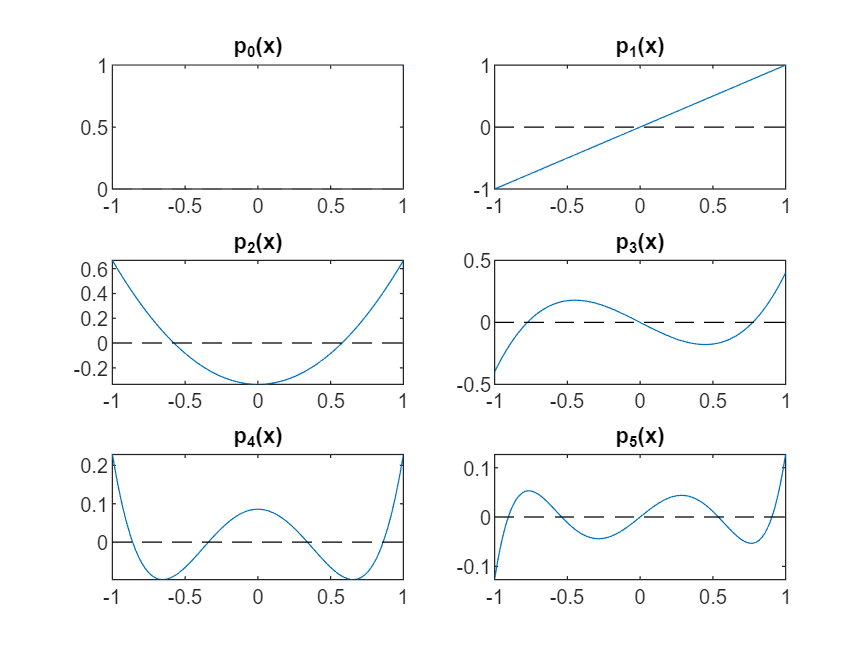

xx=linspace(-1,1,100);

for k=1:6
    subplot(3,2,k)
    pk=Pef(k,:);
    ppk=polyval(pk,xx);
    plot(xx,ppk,'-',xx,0*xx,'k--');
    title(sprintf('p_%d(x)',k-1));
end